# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL 

# FULL WRITTEN EXAMINATION -  A.Y. 2023/2024

**September 16, 2024**

# PART 2 - Design of a Controller with Requirements on the Performance against Disturbances 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure   

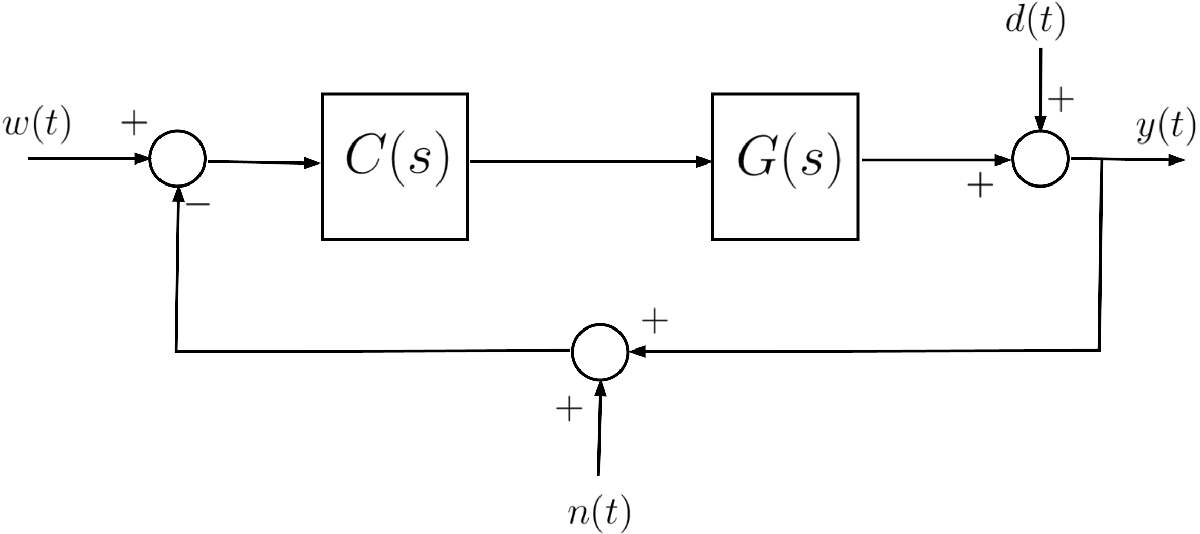	

where $G(s)$ is given by                


$$G(s) = 16\frac{(1+23s)}{(1+16\,s)\,(1+4s)}$$


### Assignment 		

**A1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- $|e(\infty)|=0$ for $w(t) = \mathbf{1}(t)$;

- For $d(t)=D \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall D \in \mathbb{R}, \; D>0$, $\omega \in \left[0.001\,,\; 0.1\right]\;\text{rad/s}$, the corresponding steady-state output $y_{d,\,\infty}(t)$ generated by the disturbance $d(t)$, with $w(t)=0$, $n(t)=0$, $\forall t$ has magnitude satisfying $|y_{d,\,\infty}(t)| \le D/10$;

- For $n(t) = N \sin(\omega t) \cdot \mathbf{1}(t)$, $\forall N \in \mathbb{R},\;N>0$, $\omega \in \left[10,\,100\right]\;\text{rad/s}$, the corresponding steady-state output $y_{n,\,\infty}(t)$ generated by the disturbance $n(t)$, with $w(t)=0$, $d(t)=0$, $\forall t$ has magnitude satisfying $|y_{n,\,\infty}(t)| \le N/100$.	

As usual, $\mathbf{1}(t)$ denotes the unit step function: $\mathbf{1}(\tau) = \left\{ \begin{array}{rcl}
0 &\longleftrightarrow& \tau <0 \\
1 &\longleftrightarrow& \tau \ge 1
\end{array} \right.$ 

% Insert your code
clear

addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

Gs = 16*(1+23*s)/((1+16*s)*(1+4*s)); 

prendiamo innanzitutto il controllore $\;C_1 =\frac{\mu_C }{s}$ per soddisfare $\left\vert e(\infty) \right\vert = 0$ for $w(t) = \mathbf{1}(t)$.

Aaggiungendo un polo in (0,0) saremo certi di non avere errore statico per w(t)=1(t).

(Settiamo$\mu_c=1$, in caso di necessità verrà modificato successivamente)

muC = 0.1;
Cs = muC/s;

Ls = Cs * Gs


Ls =
 
     36.8 s + 1.6
  -------------------
  64 s^3 + 20 s^2 + s
 
Continuous-time transfer function.


Risulta immediato che i punti 2 e 3 possono essere interpretati come vincoli su $|L\left(j\bar{\omega} \right)|$, infatti i 2 requisiti si possono tradurre nelle seguenti specifiche:


$$\left\vert L(j\,\bar \omega)\right\vert \ge 10,\; \forall \bar \omega \in \left[ \frac{1}{1000},\;\frac{1}{10}\right]\longmapsto|L(j\bar\omega)|\geq20dB,\; \forall \bar \omega \in \left[ \frac{1}{1000},\;\frac{1}{10}\right]$$
 


$$\left\vert L(j\,\bar \omega)\right\vert \le \frac{1}{100},\; \forall \bar \omega \in \left[ 10,\; 100\right]\longmapsto\left\vert L(j\,\bar \omega)\right\vert \leq -40dB,\; \forall \bar \omega \in \left[ 10,\; 100\right]$$


Ora utilizziamo il control system designer per modificare il controllore in modo da rispettare tutti i requisiti richiesti, come il posizionamento dei poli effettuato come segue:

- polo in 0 (integratore), per soddisfare il requisito dell'errore a regime nullo per ingresso a gradino $w\left(t\right)=1\left(t\right)$;

- polo in prossimità dell'origine (posizionato in -0.1), per la reiezione del disturbo a bassa frequenza, poiché poli reali lenti (vicini all'origine) rendono il sistema meno sensibile alle basse frequenze;

- polo più lontano dall'origine (posizionato in -10), per l'attenuazione del disturbo ad alta frequenza (agiasce come una sorta di filtro passa-basso);

- polo ancora più lontano dall'origine (opzionale in realtà, posizionato in -50) per gestire meglio il disturbo ad alta frequenza, attenuandolo ulteriormente: se il disturbo richiede una reiezione più aggressiva, un ulteriore polo lontano dall'origine aiuta a ridurre ancora di più la sensibilità alle alte frequenze.

controlSystemDesigner(Gs, Cs)